# HW 2 - Matlab Exercise 2 parts 1-4

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt');
% loading in the data from the csv matrix
converted_data = convert(data);
x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

S = function_handle with value:
    @(a,b,c)(sqrt(a.^2+b.^2+c.^2))


with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \textrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)';
mag_sigquared = abs(sig_sig).^2;
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

energy_sig = 2.6534e+04

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below. this does not have names on the plots, but we can make a names vector for it and add it programatically

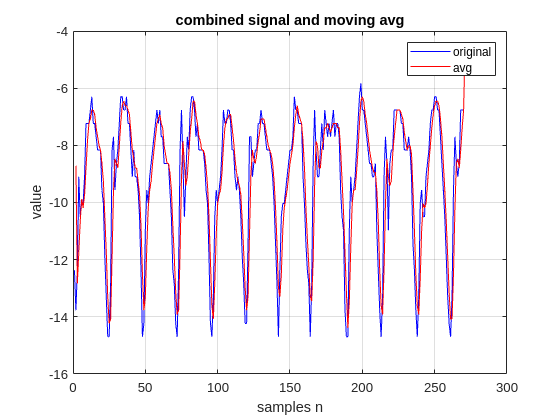

plot_avgs(x)

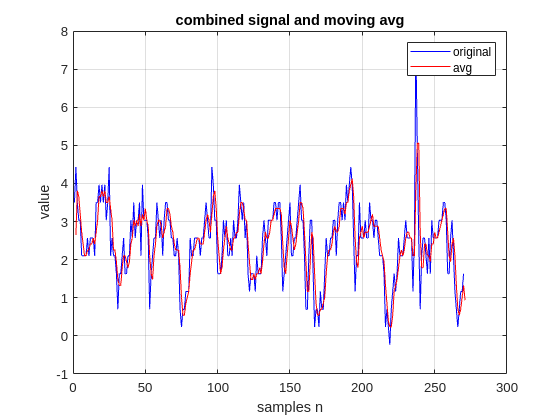

plot_avgs(y)

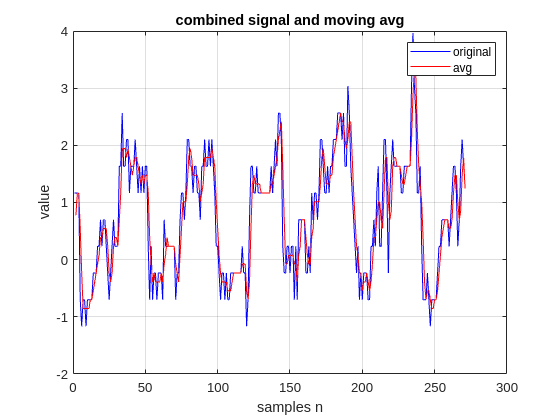

plot_avgs(z)

## get all at once with the data and converted data

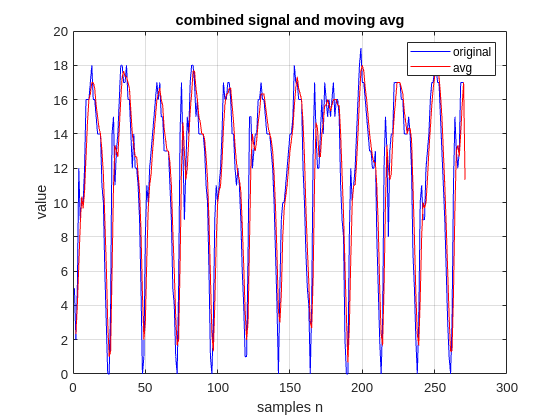

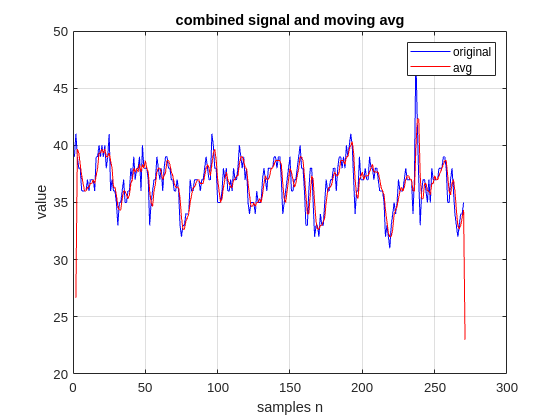

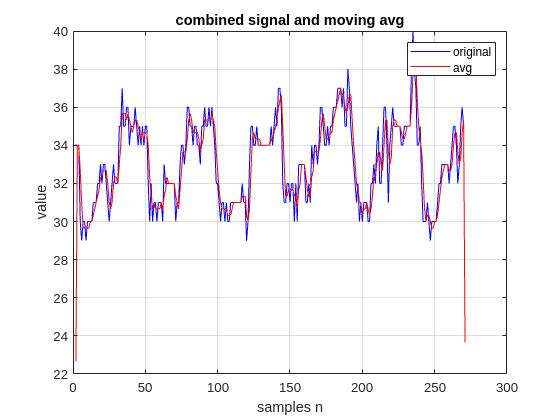

for i = 1:3
    figure
    plot_avgs(data(:,i))
    pause(.1)
    figure
    plot_avgs(converted_data(:,i))
    pause(.1)
end

## Here is the convolved impulse $\delta$ across the signals 

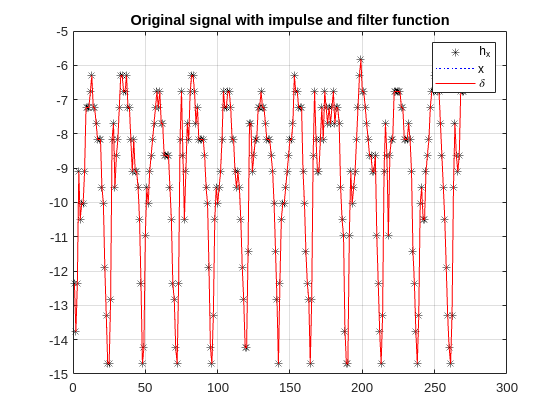

impulse = 1;
figure
conv_sig = conv(x,impulse);
hx = filter(impulse,1,x);
hy = filter(impulse,1,y);
hz = filter(impulse,1,z);
reg_range = (1:1:length(hx))';
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

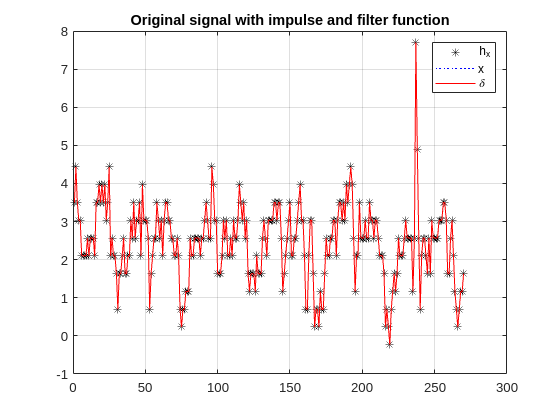


impulse = 1;
figure
conv_sig = conv(y,impulse);
reg_range = (1:1:length(hy))';
figure()
plot(reg_range,hy,'k*',1:1:length(y),y,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

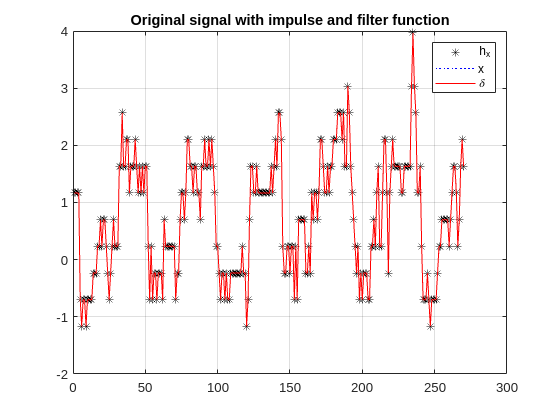


impulse = 1;
figure
conv_sig = conv(z,impulse);
reg_range = (1:1:length(hz))';
figure()
plot(reg_range,hz,'k*',1:1:length(z),z,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

## 4 Recursive system 1

These are the plots of the recursive system for problem 4 

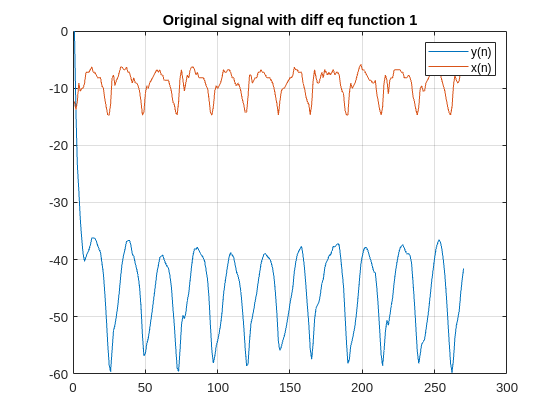

figure()
diff1_x = [diffeq_1(x),x];
plot(diff1_x)
title('Original signal with diff eq function 1')
legend("y(n)","x(n)")
grid on

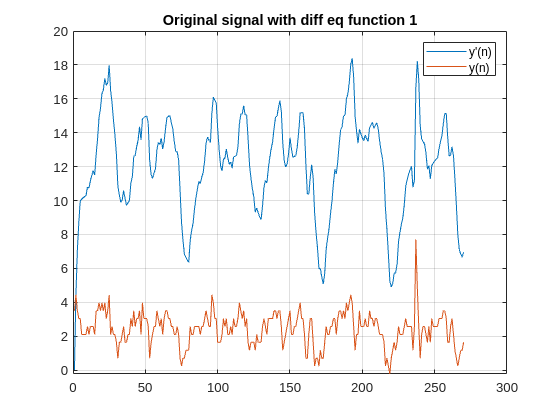


figure()
diff1_y = [diffeq_1(y),y];
plot(diff1_y)
title('Original signal with diff eq function 1')
legend("y'(n)","y(n)")
grid on

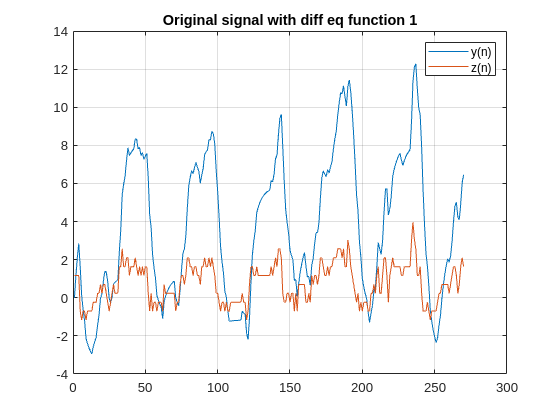


figure()
diff1_z = [diffeq_1(z),z];
plot(diff1_z)
title('Original signal with diff eq function 1')
legend("y(n)","z(n)")
grid on

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

function plot_avgs(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
plot(1:1:length(x),x,'b',2:1:(length(conv_sig)-1),conv_sig(2:end-1),'r');
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')
end


% difference eqs
function y = diffeq_1(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = .8*(y(n-1)) + x(n);
    end
end
